clear
close all

Loading Brain

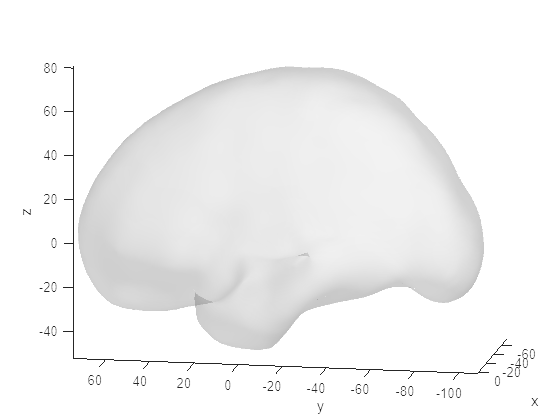

addpath("dataset/")
addpath("priv/")
addpath("scripts/")
load('simulation_points_MNI.mat','f_hull','v_hull')

hull_minmax = [-min(v_hull);max(v_hull)];

h=mvis(v_hull,f_hull); hold on; clim([0 1]); view([-100 -12])
h.FaceAlpha = .2;
camlight;


% Write brain into vtk
% Multiplied by inversion factor due to 3DSlicer standards
createVTK('brain.vtk', v_hull.*[-1,-1,1], f_hull);

clear f_hull v_hull

Defining ranges

Note: Not every combination is available, check "dataset" for available combinations of seed/curvatures/grid_size/iedist (Note: grid_size = 4 is not totally working with DEETO)

curvatures = (1:2);
seeds = (1:57);
grid_sizes = [4,8,10,15,18];
iedists = [3,5,10];

Picking electrodes (each cell is an array that define one electrode from the dataset based on the combination of their parameters)

chosen_electrodes = {};

% Many borderline electrodes
%seedsPool=[23,24,25,27,28,29,30,31,32];
%for i = 1:length(seedsPool)
%    chosen_electrodes{i} = [1,seedsPool(i),3,2];
%end
%model_name = "ManyBorderlineElectrodes";

% One electrode
%chosen_electrodes = {[1,4,4,1]}; model_name = "OneElectrode";

% Two almost overlapping electrodes
%chosen_electrodes = {[1,1,5,1],[1,25,2,1]}; model_name = "2DistantElectrodes";

% Many electrodes
seedsPool = [1,2,3,6,7,10,12,13];
for i = 1:length(seedsPool)
    chosen_electrodes{i} = [1,seedsPool(i),3,2];
end
model_name = "ManySameSizeElectrodes";

% Two curved electrodes
%chosen_electrodes = {[2,28,3,2],[2,51,2,2]}; model_name = "2CurvedElectrodes";

ct_name_file = strcat("ct_",model_name);

for i = 1:length(chosen_electrodes)
    mat_file = strcat(  'Curvature',    string(curvatures(chosen_electrodes{i}(1))), ...
                        '-Seed',        string(seeds(chosen_electrodes{i}(2))), ...
                        '-GridSize',    string(grid_sizes(chosen_electrodes{i}(3))), ...
                        '-iedist',      string(iedists(chosen_electrodes{i}(4))), ...
                        '.mat');
    if not(isfile(strcat("dataset/",mat_file)))
        error(strcat("File ",string(i),": ",mat_file," unavailable!"))
    end
end

Reading infos from dataset, creating electrodes and saving coordinates

using predefined electrode size for ellipsoid model


adding correlated noise (sigma = 0.19494) and uncorrelated noise (sigma = 0.044721). Total sigma = 0.2


distance target from last point: 0.447


using predefined electrode size for ellipsoid model


adding correlated noise (sigma = 0.19494) and uncorrelated noise (sigma = 0.044721). Total sigma = 0.2


distance target from last point: 2.3821


using predefined electrode size for ellipsoid model


adding correlated noise (sigma = 0.19494) and uncorrelated noise (sigma = 0.044721). Total sigma = 0.2


distance target from last point: 0.82488


using predefined electrode size for ellipsoid model


adding correlated noise (sigma = 0.19494) and uncorrelated noise (sigma = 0.044721). Total sigma = 0.2


distance target from last point: 1.9077


using predefined electrode size for ellipsoid model


adding correlated noise (sigma = 0.19494) and uncorrelated noise (sigma = 0.044721). Total sigma = 0.2


distance target from last point: 0.96161


using predefined electrode size for ellipsoid model


adding correlated noise (sigma = 0.19494) and uncorrelated noise (sigma = 0.044721). Total sigma = 0.2


distance target from last point: 0.94261


using predefined electrode size for ellipsoid model


adding correlated noise (sigma = 0.19494) and uncorrelated noise (sigma = 0.044721). Total sigma = 0.2


distance target from last point: 2.0241


using predefined electrode size for ellipsoid model


adding correlated noise (sigma = 0.19494) and uncorrelated noise (sigma = 0.044721). Total sigma = 0.2


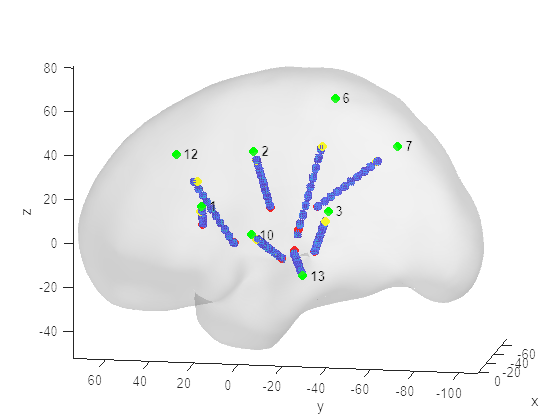

distance target from last point: 1.0414


elec_map_json_file = fopen(strcat('electrodesInfos.json'),'w');
electrodes = {};
crdDepths = {};
crdDepthsShifted = {};
weightDepths = {};

seeg_fiducial_csv_file = fopen(strcat(model_name,'_SEEG_fiducial.fcsv'),'w');
fprintf(seeg_fiducial_csv_file,"# Markups fiducial file version = 4.6\n" + ...
    "# CoordinateSystem = 0\n" + ...
    "# columns = id, x, y, z, ow, ox, oy, oz, vis, sel, lock, label, desc, associatedNodeID\n");

currLabelId = 65;    % uppercase 'A' for the label


rng(42)
for i = 1:length(chosen_electrodes)
    curvature = curvatures(chosen_electrodes{i}(1));
    seed = seeds(chosen_electrodes{i}(2));
    grid_size = grid_sizes(chosen_electrodes{i}(3));
    iedist = iedists(chosen_electrodes{i}(4));
    load(strcat('Curvature',string(curvature),'-Seed',string(seed),'-GridSize',string(grid_size),'-iedist',string(iedist),'.mat'));
    
    % Given by the paper

    %% Simulate voxels
    options=[];
    options.M1=iedist; %IED
    options.rows =  length(pos_mesh);
    options.cols =  1;
    options.adjMat = makeAdjMat(length(pos_mesh),1);
    options.thresholdValue=-1;
    options.type = 'depth';

    [crdDepth,weightDepth,elecNumDepth]=simulateVoxels(pos_mesh,repmat(normalVecMesh,length(pos_mesh),1),options); %crd: coordinates / weight: voxel weights

    %% Simulate Noise
    options.fractionAdd = 1;
    options.fractionLose = 1;
    options.sigma = .2; %noise level

    options.noiseType = 'intensity_spatial_corr';
    options.noiseDist = 'normal';
    options.repetitions = 1;
    options.thresholdValue = 0;
    options.corr_ratio = .95;
    options.image_res = 0.5;
    options.pos=pos_mesh;

    [crdDepth,weightDepth,elecNumDepth]=addnoise2electrodes(crdDepth,weightDepth,elecNumDepth,options);
    
    % -------

    clear elecNumDepth options in_brain_contacts M1

    crdDepthsShifted{1,i} = crdDepth+hull_minmax(1,:);
    crdDepths{1,i} = crdDepth;

    scatter3(crdDepth(:,1),crdDepth(:,2),crdDepth(:,3),5,weightDepth); hold on; axis image;

    % normalize weightDepth
    weightDepth = (weightDepth-min(weightDepth))/(max(weightDepth)-min(weightDepth));
    weightDepths{1,i} = weightDepth;
    
    % target point is considered as a point of the electrode
    % i use the seed point as the entry point
    % and for the target point i use a new point next to the last point
    % with a bit of a noise
    sigmaPosition = 2.5;

    diffPoint = targetPoint-pos_mesh(length(pos_mesh)-1,:); normDiffPoint = diffPoint ./ norm(diffPoint);
    targetPoint = targetPoint + sigmaPosition*(2*rand(1,3)-1).*normDiffPoint;

    diffPoint = pos_mesh(2,:)-pos_mesh(1,:); normDiffPoint = diffPoint ./ norm(diffPoint);
    headPoint = pos_mesh(1,:) + sigmaPosition*(2*rand(1,3)-1).*normDiffPoint;
    
    % Visual inspection in 3DSlicer showed that these should not be inverted
    outHeadPoint = headPoint;%.*[-1,-1,1];      
    outTargetPoint = targetPoint;%.*[-1,-1,1];
    
    % Writing fiducials on fcsv
    fprintf(seeg_fiducial_csv_file,strcat( ...                                                          %%%%%%%%%%%%%%%%%%%%%%%%%% HEAD %%%%%%%%%%%%%%%%%%%%%%%%%
        "vtkMRMLMarkupsFiducialNode_",string(2*(i-1)),',', ...                                          % node id                                               %
        string(outHeadPoint(1)),",",string(outHeadPoint(2)),",",string(outHeadPoint(3)),",", ...        % head x,y,z                                            %
        "0,0,0,1,1,1,0,", ...                                                                           % these are always the same in the example provided     %
        string(char(currLabelId)),"',,vtkMRMLModelNode21\n", ...                                        % label, decription (empty in the example) and a string %
        ...                                                                                             %%%%%%%%%%%%%%%%%%%%%%%%% TARGET %%%%%%%%%%%%%%%%%%%%%%%%
        "vtkMRMLMarkupsFiducialNode_",string(2*(i-1)+1),',', ...                                        % node id                                               %
        string(outTargetPoint(1)),",",string(outTargetPoint(2)),",",string(outTargetPoint(3)),",", ...  % target x,y,z                                          %
        "0,0,0,1,1,1,0,", ...                                                                           % always the same                                       %
        string(char(currLabelId)),"'1,,vtkMRMLScalarVolumeNode1\n"));                                   % label'1, description and another string               %
                                                                                                        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    currLabelId = currLabelId+1;
    

    scatter3(targetPoint(1,1),targetPoint(1,2),targetPoint(1,3),40,"red","filled")
    scatter3(seedPoint(1,1),seedPoint(1,2),seedPoint(1,3),40,"green","filled")
    scatter3(headPoint(1,1),headPoint(1,2),headPoint(1,3),40,"yellow","filled")
    
    text(seedPoint(1,1), seedPoint(1,2), seedPoint(1,3), sprintf('  %d', seed), 'Color', 'black', 'FontSize', 10, 'FontWeight', 'bold')

    disp(strcat("distance target from last point: ",string(norm(targetPoint - pos_mesh(length(pos_mesh),:)))))
    
    outSeedPoint = seedPoint.*[-1,-1,1];
    outPos_mesh = pos_mesh.*[-1,-1,1];

    electrode = struct("iedist",iedist, ...
        "numContacts",grid_size, ...
        "entryPoint",outSeedPoint, ...
        "targetPoint",outTargetPoint, ...
        "intermediatePoints",outPos_mesh);
    electrodes{1,i} = electrode;
end

fprintf(elec_map_json_file,'%s',jsonencode(electrodes,PrettyPrint=true));
fclose(elec_map_json_file);
fclose(seeg_fiducial_csv_file);

clear electrode electrodes iedist grid_size targetPoint elec_map_json_file sigmaTargetPosition diffPoint normDiffPoint zero seedPoint

Voxelizing: 

For every point in the [electrodes, noise], map to a voxel and create a list of collisions (points mapped to the same voxel), that will have as intensity the average of the intensities for all the points colliding

%ratios = sum(hull_minmax,1);
%definitionsRatios = ratios/min(ratios);
%definition = round(definitionsRatios*400);

%PixelSize = sum(hull_minmax,1)./definition;
pixelSize = 1;
matrixSize = round(sum(hull_minmax,1));
maxValueFromExample = 3071;

VoxelizedElectrodes = zeros(matrixSize,"single");
collisionsList = {};
for j = 1:length(crdDepthsShifted)
    crdDepthShifted = round(crdDepthsShifted{1,j});
    weightDepth = round(weightDepths{1,j}*maxValueFromExample);
    for i = 1:length(crdDepthShifted)
        toVoxel = min(max(crdDepthShifted(i,:),1),10000);
        found = false;
        for k = 1:height(collisionsList)
            if all(collisionsList{k,1} == toVoxel)
                collisionsList{k,2} = [collisionsList{k,2},weightDepth(i)];
                found = true;
                break;
            end
        end
        if not(found)
            if VoxelizedElectrodes(toVoxel(1),toVoxel(2),toVoxel(3)) == 0
                VoxelizedElectrodes(toVoxel(1),toVoxel(2),toVoxel(3)) = weightDepth(i);
            else
                collisionsList{height(collisionsList)+1,1} = toVoxel;
                collisionsList{height(collisionsList),2} = [VoxelizedElectrodes(toVoxel(1),toVoxel(2),toVoxel(3)),weightDepth(i)];
            end
        end
    end
end

%% Averaging collisions
for i = 1:height(collisionsList)
    VoxelizedElectrodes(collisionsList{i,1}(1),collisionsList{i,1}(2),collisionsList{i,1}(3)) = mean(collisionsList{i,2});
end

clear found weightDepth ratios definition definitionsRatios i j maxValueFromExample voxel

Packing CT infos, brain VTK, electrodes informations and fiducial markups for head and target points starting from a previously existing CT

% Setting infos from previously given CT image
outinfos = niftiinfo("ct.nii.gz");
outinfos.ImageSize = size(VoxelizedElectrodes);
%outinfos.Version = 'NIfTI1';
%outinfos.Description = "";
outinfos.PixelDimensions = repmat([pixelSize],1,3);
outinfos.Transform.T(1,1) = 1.0;
outinfos.Transform.T(2,2) = 1.0;
outinfos.Transform.T(3,3) = 1.0;
outinfos.Transform.T(4,1:3) = -hull_minmax(1,:);
outinfos.raw.dim(2:4) = size(VoxelizedElectrodes);
outinfos.raw.pixdim(2:4) = pixelSize;
outinfos.raw.qoffset_x = -hull_minmax(1,1);
outinfos.raw.qoffset_y = -hull_minmax(1,2);
outinfos.raw.qoffset_z = -hull_minmax(1,3);
outinfos.raw.srow_x = outinfos.Transform.T(:,1)';
outinfos.raw.srow_y = outinfos.Transform.T(:,2)';
outinfos.raw.srow_z = outinfos.Transform.T(:,3)';

outinfos.Filename = strcat(ct_name_file,".nii.gz");
niftiwrite(VoxelizedElectrodes,ct_name_file,outinfos,"Compressed",true);
out_folder = "out";

if exist(out_folder, 'dir') ~= 7
    mkdir(out_folder);
end
modelNameFullPath = fullfile(out_folder, model_name);
%infos2 = niftiinfo(brain_name_file);
zip(strcat(modelNameFullPath,".zip"), ...
    {convertStringsToChars(strcat(ct_name_file,".nii.gz")), ...
    convertStringsToChars(strcat("electrodesInfos.json")), ...
    convertStringsToChars("brain.vtk"), ...
    convertStringsToChars(strcat(model_name,"_SEEG_fiducial.fcsv"))});
delete(strcat(ct_name_file,".nii.gz"));
delete(strcat("electrodesInfos.json"));
delete('brain.vtk');
delete(strcat(model_name,"_SEEG_fiducial.fcsv"));

clear ct_name_file overwrite